%Finding out what clusters belong to which layers


%load("COV_ks.mat", "kc","k","kp","A");
%load("COV_ClustersSupra_run10.mat", "ClustersSupra");
%"cEBM_clusters_eg2_k171.mat"
load("cEBM_step2_reg_eg95_d5_wFunction.mat", "ClustersSupra","kc","k","kp","A")
Al = A;

kpl=kp;
ClustersSupra = ClustersSupra; %length(unique(ClustersSupra))
k=k;

un_len = max(ClustersSupra);

%colors = random_color(un_len); %fix so its not all same colors

L = 49; % components
x=1;
z=464; %number of nodes
nodes = 464;
y=1;

clusterssupra_total = [];

cluster_layer_strength= [];

cluster_layer = zeros(un_len,L);

layer_nodes_per_cluster = []; %matrix that is un_len each matrix has zeros(k_labels,64);

for i=1:un_len
    layer_nodes_per_cluster = [layer_nodes_per_cluster, {zeros(L,464)}];
end


cluster_strength_layer = cell(L,1,kc); %cretaes the intercluster strength per layer per cluster
layers_in_cluster = cell(1,un_len); %tells you which layers are in the cluster
sum_of_edges = cell(L,1,kc); %
norm_sum_of_edges = cell(L,1,kc); %

%change 64 to 464
for i=1:kc
    for subject=1:L
        cluster_strength_layer{subject,1,i}= zeros(464,464);
    end
end

example = cluster_strength_layer{1,1,1};

for cindex=1:L
    
    A = Al{cindex};

   
    k_labels = unique(ClustersSupra(x:z));
    clusterssupra_total = [clusterssupra_total, {k_labels}];
    
    
    for index=1:length(k_labels)
        label = k_labels(index);
        cluster_layer(label,cindex) = 1; %mark present in layer
        new_nodes = find(ClustersSupra(x:z)==label)'; 
        

        
        %if label <= kc
            past=new_nodes(1); 
            layers_in_cluster{label} = [layers_in_cluster{label} cindex];
            
            for new=1:length(new_nodes)
                if new_nodes(new) >= past
                    for future=1:length(new_nodes)
                        future_node = new_nodes(future);
                        %check_old = A(past,future_node);
                        cluster_strength_layer{cindex,1,label}(past,future_node) = A(past,future_node);
                        %check = cluster_strength_layer{cindex,1,label}(past,future_node);
                        %check_new = cluster_strength_layer{cindex,1,label};
                        
                    end
                    past = new_nodes(new);
                end
            end
            
           %end
         for new=1:length(new_nodes)
             layer_nodes_per_cluster{1,label}(cindex,new_nodes(new)) = 1;
         end
        
    end

    x=x+nodes;
    z=(x+nodes-1);
  
end

for i=1:un_len
    % a = length(layers_in_cluster{1,46});
    if length(layers_in_cluster{1,i}) > 1
        fprintf("Layer %d has multiple networks",i)
    end
end

Layer 1 has multiple networks

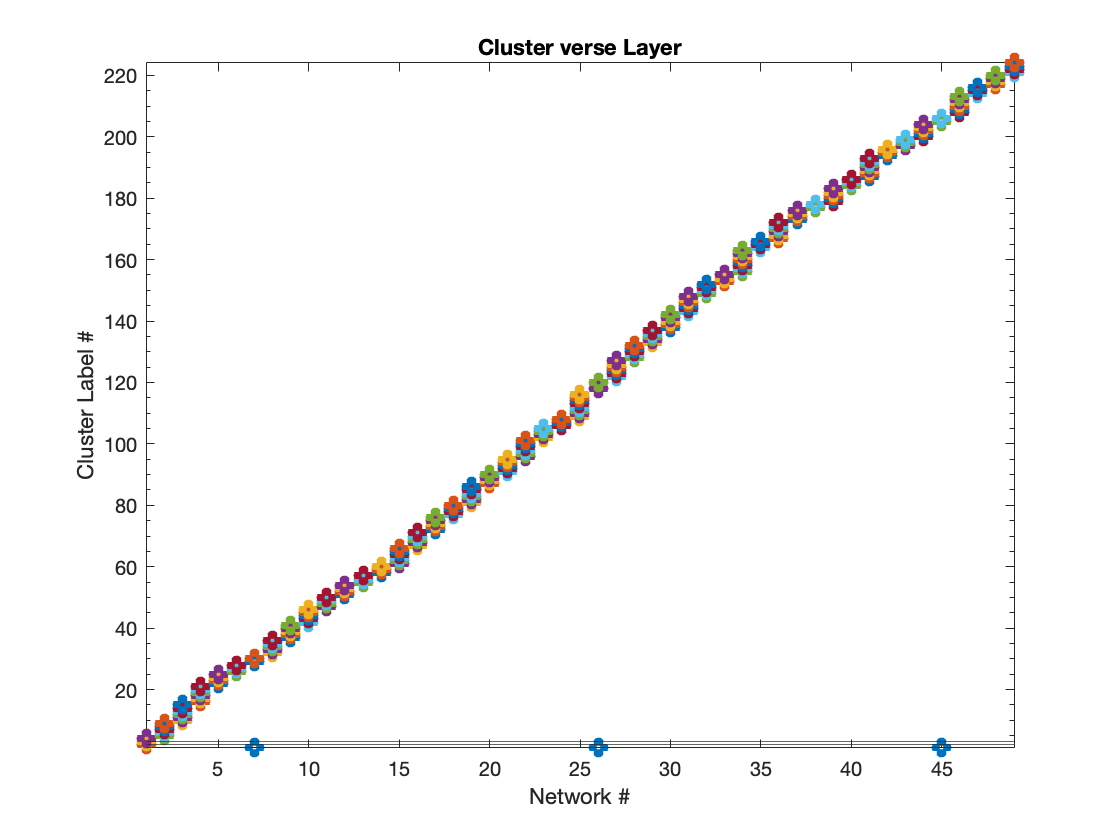


example2 = cluster_strength_layer{7,1,1};
%INTERCLUSTER STRENGTH SUM
% for i=1:kc
%     
%     for subject=1:L
%         B = cluster_strength_layer{subject,1,i};
%         C = Al{1,subject};
%         norm_sum_of_edges{subject,1,i}= sum(B,'all')/sum(C,'all');
%         sum_of_edges{subject,1,i}= sum(B,'all');
%     end
% end


% %new section 
%INTERCLUSTER STRENGTH SUM
for i=1:kc
    list_of_layers = layers_in_cluster{1,i};
    for cluster_index=1:length(list_of_layers)
        subject = list_of_layers(1,cluster_index);
        B = cluster_strength_layer{subject,1,i};
        C = Al{1,subject};
        norm_sum_of_edges{subject,1,i}= sum(B,'all')/sum(C,'all');
        sum_of_edges{subject,1,i}= sum(B,'all');
    end
end
% % end of new section

%Plotting data stored

figure;

M = cluster_layer;
% Loop over rows
for i = 1:size(M, 1)
    % Find column indices where there is a 1
    ind = find(M(i,:)==1);
    
    % Plot indices against row number
    plot(ind, repmat(i, size(ind)), 'o','LineWidth',4);
    hold on;
end

% Set axis labels and limits
xlabel('Network #');
ylabel('Cluster Label #');
xlim([1 size(M, 2)]);
ylim([1 size(M, 1)]);
title("Cluster verse Layer");
set(gca,'YMinorTick', 'on');
yline(1:3);
hold off;

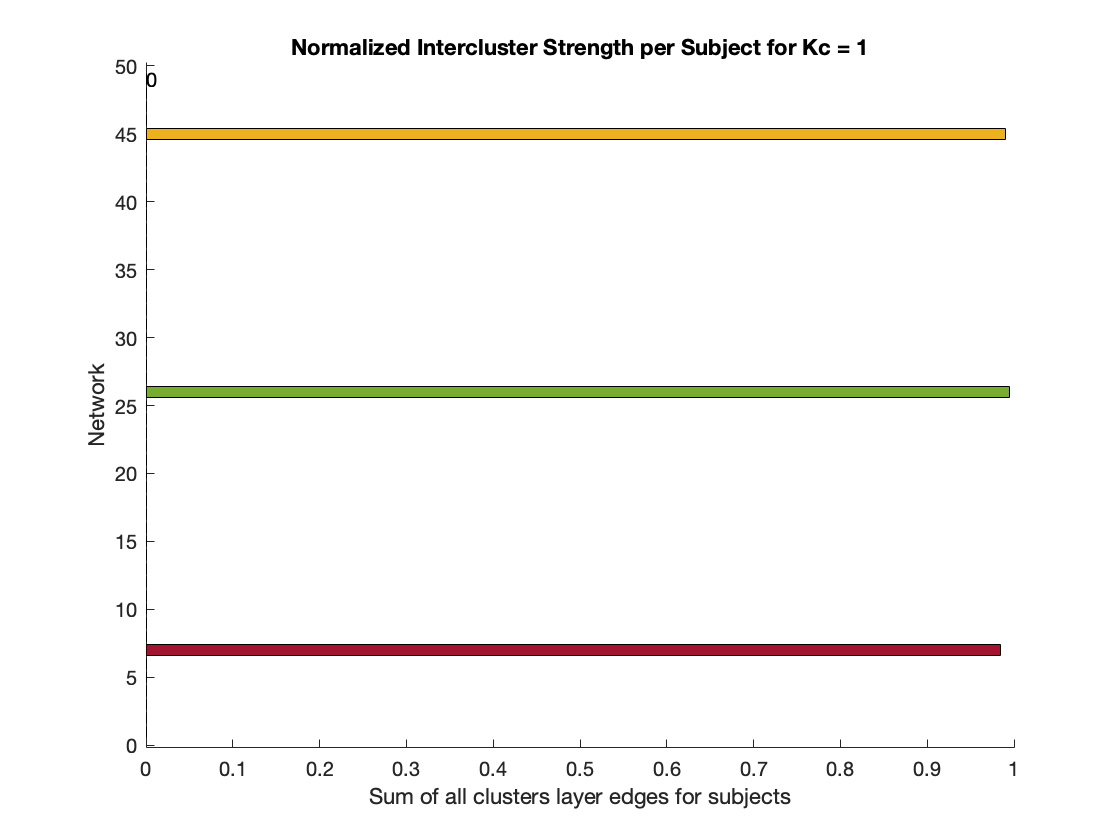




figure;
figure('Position', [0 0 800 800])



%normalized graph
for cindex = 1:kc
    
    
    % Create a vector of row indices for the y-axis
    sumy = norm_sum_of_edges(:,:,cindex);
    
    tf = cellfun('isempty',sumy); % true for empty cells
    sumy(tf) = {0};
    
    % Create a vector of row indices for the y-axis
    y = 1:size(sumy, 1);
    
    % Create a figure for the bar graph
    figure;
    
    % Loop over the rows of the sumy variable and plot the values as a bar graph
    for i = 1:size(sumy, 1)
        % Extract the values from the current row of the sumy variable
        row_values = cell2mat(sumy(i,:));
        hold on
        % Plot the values as a horizontal bar graph
        barh(y(i), row_values);
        
    
    end
    
        hold off
        % Add labels to the bars
        text(row_values, y(i)*ones(size(row_values)), num2str(row_values), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle');
        
        % Add a title to the plot
        title(sprintf('Normalized Intercluster Strength per Subject for Kc = %d', cindex));
        
        % Set the y-axis label
        ylabel('Network');
        xlabel("Sum of all clusters layer edges for subjects")
end